**Problem 1.a**

clear; clc;

rev = @(x) (2)*x(1)^2+x(2)^2-(x(1)*x(2))-8*x(1)-3*x(2); % Revenue function
x0 = [2; 1]; % Initial guess
A = [3000 1000]; % Cost for TV and radio ads
b = [10000]; % Budget constraint
Aeq = []; 
Beq = [];
lb = zeros(2,1); % Inequality constraints (greater than or equal to 0)

options = optimset('Algorithm','interior-point', 'Display', 'off');

[x,fval,exitflag,output,lambda,grad,hessian] = fmincon(rev, x0, A, b, Aeq, Beq, lb, [], [], options);

disp(x);

    2.4643
    2.6071




% Since we can floor or ceil radio without breaking our budget constraint,
% we should double check which one gives us the higher revenue
x1 = [2;2]; % 2 TV ads, 2 radio ads
x2 = [2;3]; % 2 TV ads, 3 radio ads
x3 = [2;4]; % 2 TV ads, 4 radio ads
rev1 = rev(x1);
disp(rev1);

   -14



rev2 = rev(x2);
disp(rev2)

   -14



rev3 = rev(x3);
disp(rev3)

   -12



**Problem 1.c**

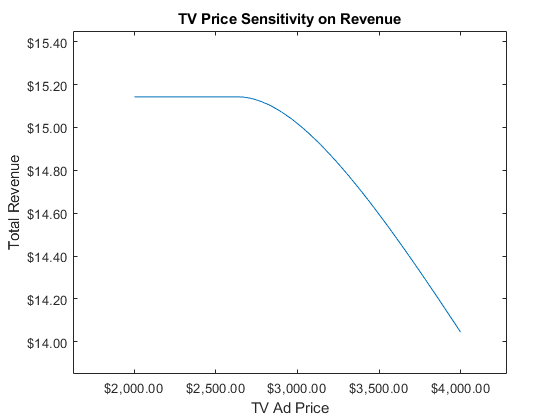

clear; clc;

TV = 2000:4000; % Price range of TV ads
z = zeros (5,numel(TV)); % Create a zero matrix for storing results

rev = @(x) (2)*x(1)^2+x(2)^2-(x(1)*x(2))-8*x(1)-3*x(2); % Revenue function
x0 = [2; 1]; % Initial guess
b = [10000]; % Budget constraint
Aeq = []; 
Beq = [];
lb = zeros(2,1); % Inequality constraints (greater than or equal to 0)
options = optimset('Algorithm','interior-point', 'Display', 'off');

for k = 1:numel(TV)
    TV1 = TV(k);   % number of women viewers
    A = [TV1 1000]; % Cost for TV and radio ads
    [x,fval,exitflag,output,lambda,grad,hessian] = fmincon(rev, x0, A, b, Aeq, Beq, lb, [], [], options);
    
    z ([1 2], k) = x; % Stores TV ads in row 1, radio ads in row 2; floors to next lowest integer
    z (3, k) = (-2)*z(1,k)^2-z(2,k)^2+z(1,k)*z(2,k)+8*z(1,k)+3*z(2,k); % Stores total continuous revenue in row 3
    z (4, k) = TV(k); % Stores changing constraint price of TV ads from $2000 to $4000 in row 4
    z (5, k) = z(1,k)*z(4,k)+z(2,k)*1000; % Stores calculated total cost in terms for 1-min block commercial (discretized)
end

plot(TV,z(3,:));
ylabel('Total Revenue')
xlabel({'TV Ad Price'})
title('TV Price Sensitivity on Revenue')
ytickformat('usd')
xtickformat('usd')
xlim([1623 4285])
ylim([13.85 15.45])

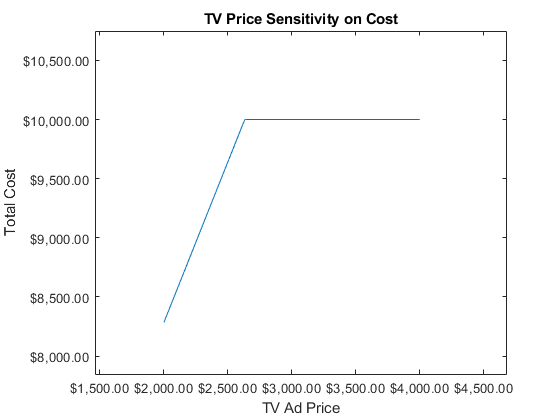


plot(TV,z(5,:));
ylabel('Total Cost')
xlabel({'TV Ad Price'})
title('TV Price Sensitivity on Cost')
ytickformat('usd')
xtickformat('usd')
xlim([1461 4682])
ylim([7849 10748])

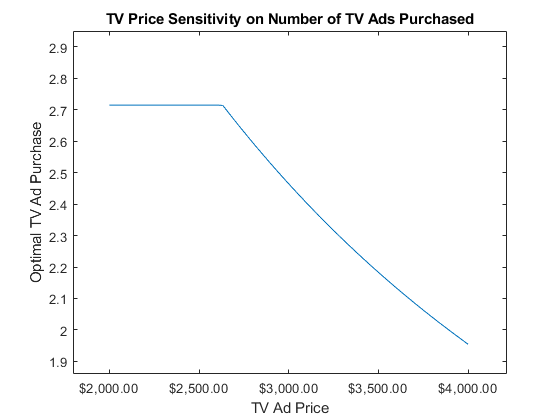


plot(TV,z(1,:));
ylabel('Optimal TV Ad Purchase')
xlabel({'TV Ad Price'})
title('TV Price Sensitivity on Number of TV Ads Purchased')
xtickformat('usd')
xlim([1797 4217])
ylim([1.86 2.95])